# facTRK for Tensor-Regression Video Deblur

clear;clc;close all;
addpath('../deblurring')
addpath('../tproduct toolbox 2.0 (transform)/')

%import data
load mri;                               %loads mri video as order-4 tensor
X = squeeze(double(D));                 %gets rid of dimension 1 mode
X = X(:,:,1:12);                        %takes only first 12 frames                       
[m1,n1,p] = size(X);                    %m1 = 128, n1 = 128, p = 12

%blur
h1 = fspecial('gaussian',[5,5],2);       %builds a Gaussian low-pass filter
[m2,n2] = size(h1);                      %size 5x5 (m2=5, n2 = 5)

h2 = fspecial('average',[5,5]);       %builds an averaging filter
[m3,n3] = size(h2);                      %size 5x5 (m2=5, n2 = 5)

m = m1+m2-1;                            %m = n = 132 (gives room for the 
n = n1+n2-1;                            %  convolutions at the edges)

mstar = m + m3 - 1

mstar = 136

nstar = n + n3 - 1

nstar = 136


Y1  = zeros(m1,n1,p);                    %build blurry video tensor
Y2  = zeros(m1,n1,p); 
for i = 1:p                             %using first filter
    Y1(:,:,i) = imfilter(X(:,:,i),h1,'symmetric');
end
for i = 1:p                             %using second filter
    Y2(:,:,i) = imfilter(Y1(:,:,i),h2,'symmetric');
end

s = floor((m2-1)/2);                    %calculates number of edge pad pixels
t = floor((n2-1)/2);


Y_pad = zeros(m,n,p);                   %pads and reorders modes for regression
Y_pad1 = zeros(m,n,p);
Y_pad_reorder = zeros(n,p,m);
for k = 1:p
    %y_pad(:,:,k) = padarray(y(:,:,k),[s,t],'symmetric','both');
    Y_pad(:,:,k) = padarray(Y2(:,:,k),[s,t],'replicate','both');
    Y_pad1(:,:,k) = padarray(Y1(:,:,k),[s,t],'replicate','both');
    for i = 1:m
        for j = 1:n
            Y_pad_reorder(j,k,i) = Y_pad(i,j,k);
            Z_true = permute(Y_pad1,[2,3,1]);
        end
    end
end

%builds tensor representation of filter
A1 = conv2tensor([m1,n1],h1); % size: n x n1 x m
A2 = conv2tensor([m1,n1+4],h2);   % size: nstar x n x mstar
A2 = A2(1:n,:,:);

%calculate least-norm solution
X_ln = tprod(tpinv(tprod(A2,A1)),Y_pad_reorder);

### Initializing with Zero Tensor

%solve system, initializing at 0 tensor
X0 = zeros(n1,p,m);

%apply tensor regression technique
num_its = 100000;
X_true = zeros(size(X0));
for i = 1:size(X,2)
    X_true(:,:,i) = X(:,i,:);
end
[Z,errs,res_errs_zero,ln_errs,res_ln_errs,norms] = facTRK_err(A2,A1,Y_pad_reorder,X0,Z_true,X_true,X_ln,num_its);

%remove padding
Z = Z(:,:,1:m1);

%permute modes back to original video shape
Z = permute(Z,[3,1,2]); % n1 x p x m1 -> m1 x n1 x p

%remove ringing artifacts
Z(Z<0) = 0;

Z_zero = Z;

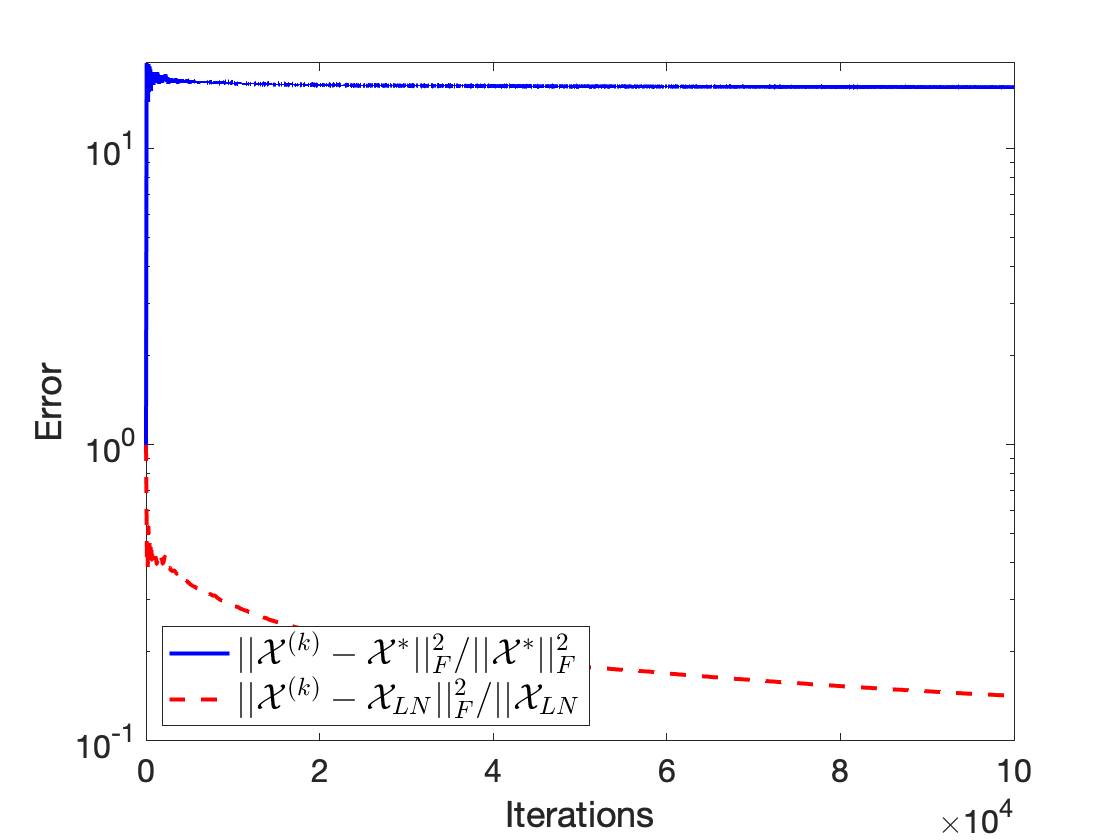

figure(1);
semilogy(0:num_its,errs,'b-',0:num_its,ln_errs,'r--','LineWidth',2)
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F^2/||\mathcal{X}^*||_F^2$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F^2/||\mathcal{X}_{LN}$','FontSize',18,'Interpreter','latex','Location','southwest')
savefig('figs/facTRK_deblurring_error_zeroinitialization.fig')
saveas(gcf,'figs/facTRK_deblurring_error_zeroinitialization.png')

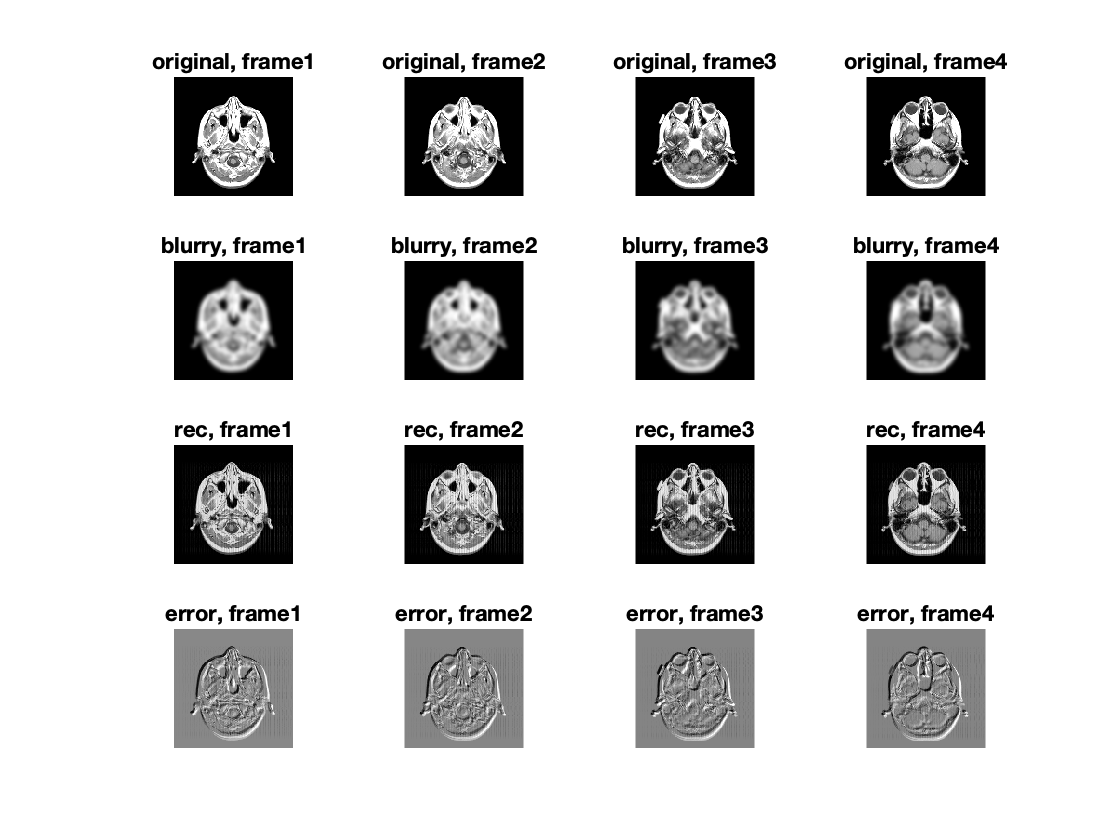

figure(3);
it = 4;
for i = 1:it
    subplot(4,it,i)
    imagesc(X(:,:,i));axis image off;colormap gray
    title(sprintf('original, frame%d',i))

    subplot(4,it,i+it)
    imagesc(Y2(:,:,i));axis image off;colormap gray
    title(sprintf('blurry, frame%d',i))
    
    subplot(4,it,i+2*it)
    imagesc(Z(:,:,i));axis image off;colormap gray
    title(sprintf('rec, frame%d',i)) 

    subplot(4,it,i+3*it)
    imagesc(X(:,:,i) - Z(:,:,i));axis image off;colormap gray
    title(sprintf('error, frame%d',i))
end

savefig('figs/facTRK_deblurring_zeroinitialization.fig')
saveas(gcf,'figs/facTRK_deblurring_zeroinitialization.png')

It looks like we might be converging to the least-norm solution, so to avoid this, let's try initializing with the blurry image!

### Initializing with Noisy Image

%solve system
%builds initial iterate tensor from noisy image tensor
X0 = zeros([n1,p,m]);
X0(:,:,1:size(Y2,2)) = permute(Y2,[2,3,1]);

%apply tensor regression technique
X_true = zeros(size(X0));
for i = 1:size(X,2)
    X_true(:,:,i) = X(:,i,:);
end
[Z,errs,res_errs_blurry,ln_errs,res_ln_errs,norms] = facTRK_err(A2,A1,Y_pad_reorder,X0,Z_true,X_true,X_ln,num_its);

%remove padding
Z = Z(:,:,1:m1);

%permute modes back to original video shape
Z = permute(Z,[3,1,2]); % n1 x p x m1 -> m1 x n1 x p

%remove ringing artifacts
Z(Z<0) = 0;

Z_blurry = Z;

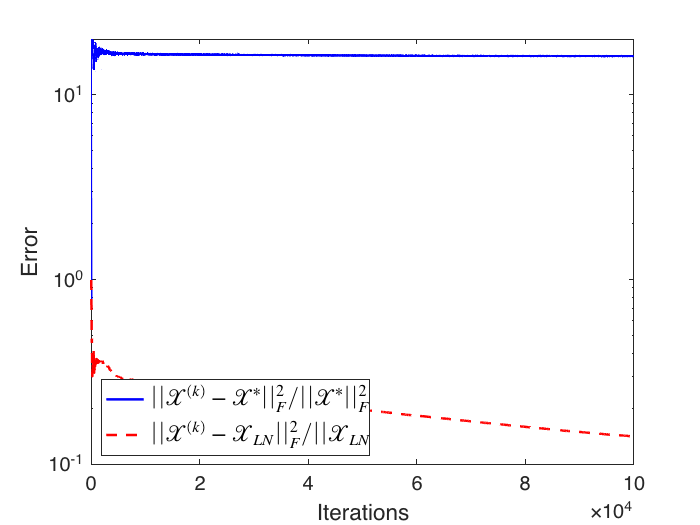

figure(1);
semilogy(0:num_its,errs,'b-',0:num_its,ln_errs,'r--','LineWidth',2)
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F^2/||\mathcal{X}^*||_F^2$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F^2/||\mathcal{X}_{LN}$','FontSize',18,'Interpreter','latex','Location','southwest')
savefig('figs/facTRK_deblurring_error_blurryinitialization.fig')
saveas(gcf,'figs/facTRK_deblurring_error_blurryinitialization.png')

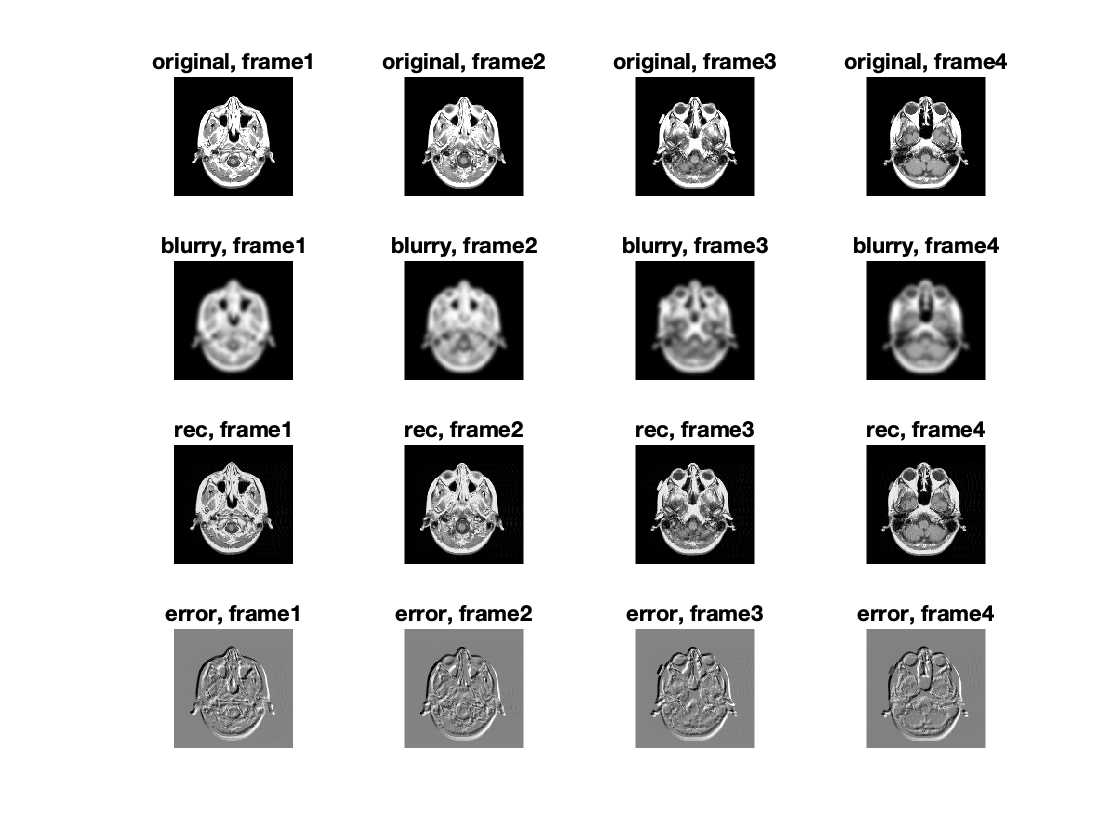

figure(3);
it = 4;
for i = 1:it
    subplot(4,it,i)
    imagesc(X(:,:,i));axis image off;colormap gray
    title(sprintf('original, frame%d',i))

    subplot(4,it,i+it)
    imagesc(Y2(:,:,i));axis image off;colormap gray
    title(sprintf('blurry, frame%d',i))
    
    subplot(4,it,i+2*it)
    imagesc(Z(:,:,i));axis image off;colormap gray
    title(sprintf('rec, frame%d',i)) 

    subplot(4,it,i+3*it)
    imagesc(X(:,:,i) - Z(:,:,i));axis image off;colormap gray
    title(sprintf('error, frame%d',i))
end

savefig('figs/facTRK_deblurring_blurryinitialization.fig')
saveas(gcf,'figs/facTRK_deblurring_blurryinitialization.png')

### Initializing randomly

%solve system, initializing at 0 tensor
X0 = 88*rand(n1,p,m);

%apply tensor regression technique
X_true = zeros(size(X0));
for i = 1:size(X,2)
    X_true(:,:,i) = X(:,i,:);
end
[Z,errs,res_errs_rand,ln_errs,res_ln_errs,norms] = facTRK_err(A2,A1,Y_pad_reorder,X0,Z_true,X_true,X_ln,num_its);

%remove padding
Z = Z(:,:,1:m1);

%permute modes back to original video shape
Z = permute(Z,[3,1,2]); % n1 x p x m1 -> m1 x n1 x p

%remove ringing artifacts
Z(Z<0) = 0;

Z_rand = Z;

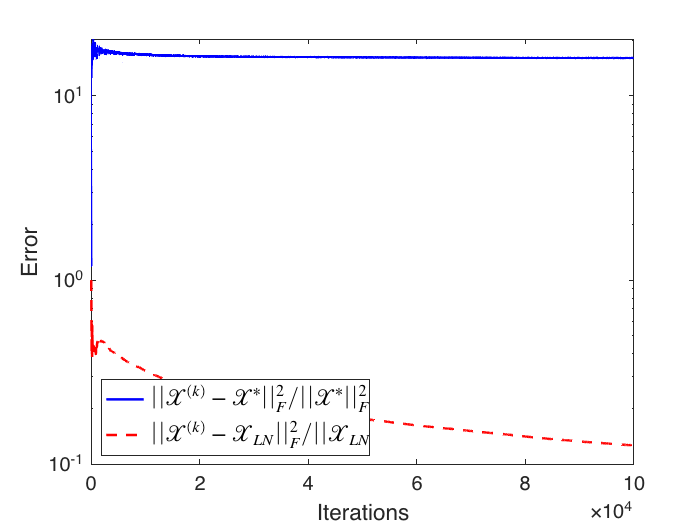

figure(1);
semilogy(0:num_its,errs,'b-',0:num_its,ln_errs,'r--','LineWidth',2)
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F^2/||\mathcal{X}^*||_F^2$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F^2/||\mathcal{X}_{LN}$','FontSize',18,'Interpreter','latex','Location','southwest')
savefig('figs/facTRK_deblurring_error_randinitialization.fig')
saveas(gcf,'figs/facTRK_deblurring_error_randinitialization.png')

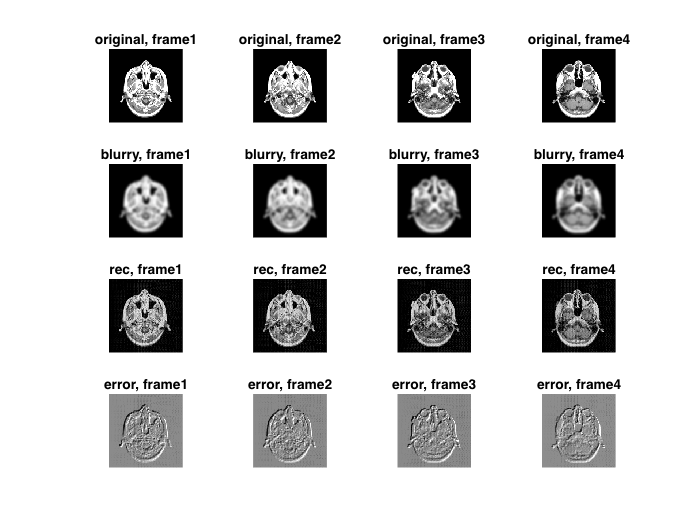

figure(3);
it = 4;
for i = 1:it
    subplot(4,it,i)
    imagesc(X(:,:,i));axis image off;colormap gray
    title(sprintf('original, frame%d',i))

    subplot(4,it,i+it)
    imagesc(Y2(:,:,i));axis image off;colormap gray
    title(sprintf('blurry, frame%d',i))
    
    subplot(4,it,i+2*it)
    imagesc(Z(:,:,i));axis image off;colormap gray
    title(sprintf('rec, frame%d',i)) 

    subplot(4,it,i+3*it)
    imagesc(X(:,:,i) - Z(:,:,i));axis image off;colormap gray
    title(sprintf('error, frame%d',i))
end

savefig('figs/facTRK_deblurring_randinitialization.fig')
saveas(gcf,'figs/facTRK_deblurring_randinitialization.png')

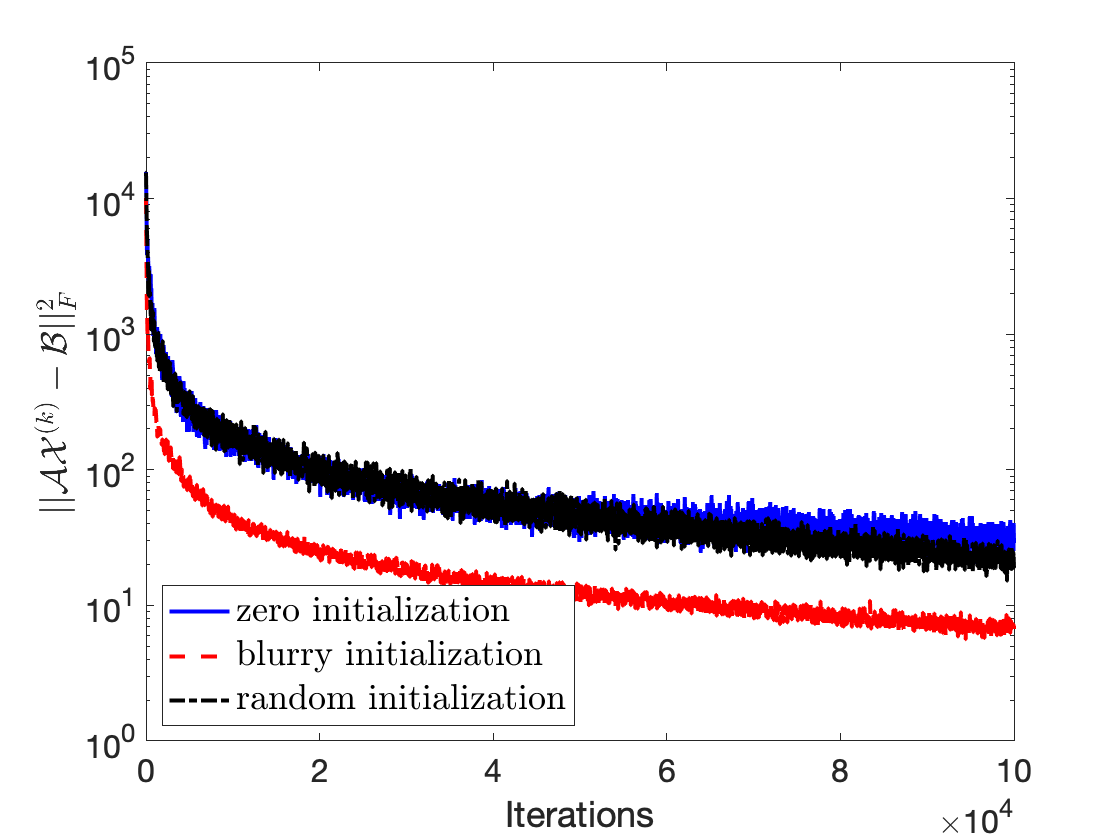

%plot residual errors
figure(11);
semilogy(0:num_its,res_errs_zero,'b-',0:num_its,res_errs_blurry,'r--',0:num_its,res_errs_rand,'k-.','LineWidth',2)
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('$||\mathcal{A} \mathcal{X}^{(k)} - \mathcal{B}||_F^2$','FontSize',18,'Interpreter','latex') 
legend('zero initialization', 'blurry initialization', 'random initialization','FontSize',18,'Interpreter','latex','Location','southwest')
savefig('figs/facTRK_deblurring_reserror.fig')
saveas(gcf,'figs/facTRK_deblurring_reserror.png')

X_ln = X_ln(:,:,1:m1);
X_LN = permute(X_ln,[1,3,2]);

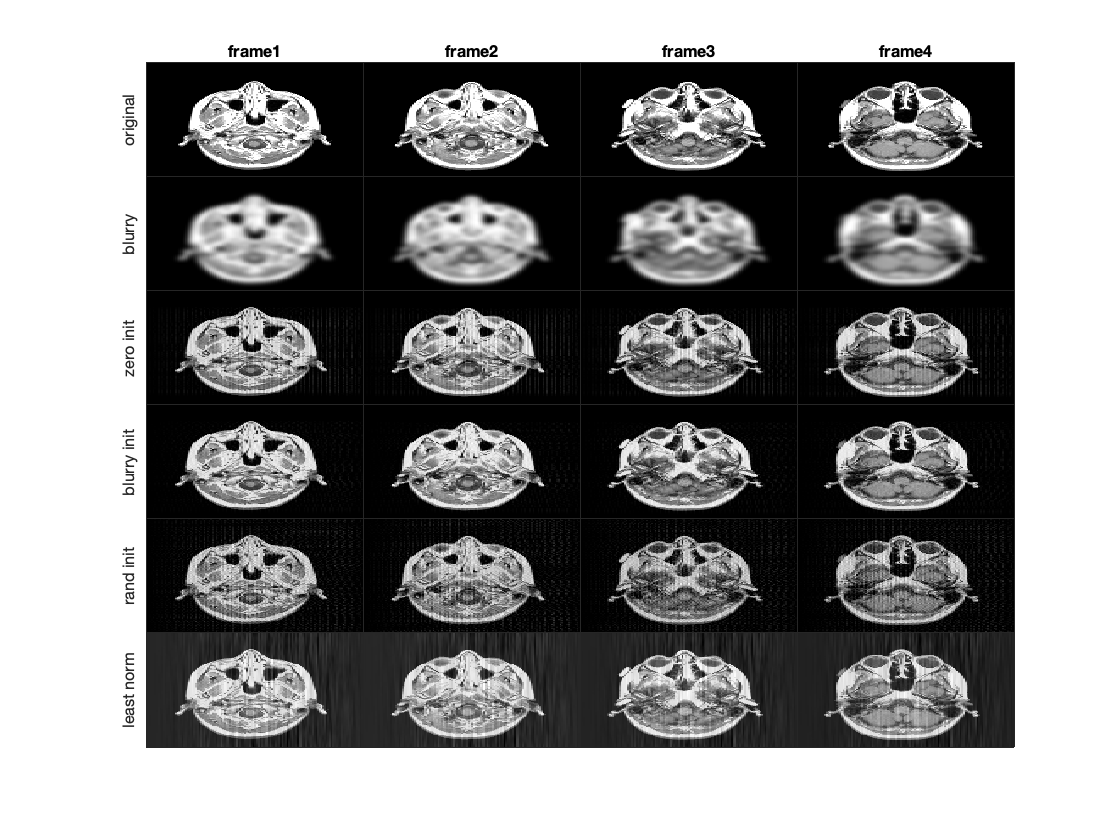

t = tiledlayout(6,4,'TileSpacing','none');

for i = 1:4
    nexttile;
    imagesc(X(:,:,i));colormap gray
    %axis equal
    %axis tight
    title(sprintf('frame%d',i), 'FontSize',8)
    if i == 1
        ylabel("original",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Y2(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_zero(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("zero init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_blurry(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_rand(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("rand init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(permute(X_LN(:,:,i),[2,1,3]));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("least norm",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 8 12]); %x_width=10cm y_width=15cm

savefig('figs/facTRK_deblurring.fig')
saveas(gcf,'figs/facTRK_deblurring.png')